#  vbcxdImport data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 24-May-2021 17:57:53

## Setup the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 20);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:T652";

% Specify column names and types
opts.VariableNames = ["M2_Amp_X_352Dhr", "M2_Amp_Y_352D", "M2_Phase_X_381Dhr", "M2_Phase_Y_381D", "S2_Amp_X_359Dhr", "S2_Amp_Y_359D", "S2_Phase_X_362Dhr", "S2_Phase_Y_362D", "N2_Amp_X_402Dhr", "N2_Amp_Y_402D", "N2_Phase_X_418Dhr", "N2_Phase_Y_418D", "K1_Amp_X_361Dhr", "K1_Amp_Y_361D", "K1_Phase_X_364Dhr", "K1_Phase_Y_364D", "O1_Amp_X_367Dhr", "O1_Amp_Y_367D", "O1_Phase_X_354Dhr", "O1_Phase_Y_354D"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
tbl = readtable("D:\OneDrive - BUET\Advanced HAMELS 15.05.2021\Final Dataset 2019-2021\M2 S2 N2 O1 K1 2019-2021 No regress For MATLAB .xlsx", opts, "UseExcel", false);


## Convert to output type

M2_Amp_X_352Dhr = tbl.M2_Amp_X_352Dhr;
M2_Amp_Y_352D = tbl.M2_Amp_Y_352D;
M2_Phase_X_381Dhr = tbl.M2_Phase_X_381Dhr;
M2_Phase_Y_381D = tbl.M2_Phase_Y_381D;
S2_Amp_X_359Dhr = tbl.S2_Amp_X_359Dhr;
S2_Amp_Y_359D = tbl.S2_Amp_Y_359D;
S2_Phase_X_362Dhr = tbl.S2_Phase_X_362Dhr;
S2_Phase_Y_362D = tbl.S2_Phase_Y_362D;
N2_Amp_X_402Dhr = tbl.N2_Amp_X_402Dhr;
N2_Amp_Y_402D = tbl.N2_Amp_Y_402D;
N2_Phase_X_418Dhr = tbl.N2_Phase_X_418Dhr;
N2_Phase_Y_418D = tbl.N2_Phase_Y_418D;
K1_Amp_X_361Dhr = tbl.K1_Amp_X_361Dhr;
K1_Amp_Y_361D = tbl.K1_Amp_Y_361D;
K1_Phase_X_364Dhr = tbl.K1_Phase_X_364Dhr;
K1_Phase_Y_364D = tbl.K1_Phase_Y_364D;
O1_Amp_X_367Dhr = tbl.O1_Amp_X_367Dhr;
O1_Amp_Y_367D = tbl.O1_Amp_Y_367D;
O1_Phase_X_354Dhr = tbl.O1_Phase_X_354Dhr;
O1_Phase_Y_354D = tbl.O1_Phase_Y_354D;

## Clear temporary variables

clear opts tbl

## 1. M2 Amp: Poly 8

`Linear model Poly8:`

`     f(x) = p1*x^8 + p2*x^7 + p3*x^6 + p4*x^5 + `

`                    p5*x^4 + p6*x^3 + p7*x^2 + p8*x + p9`

`       where x is normalized by mean 164.3 and std 95.88`

`Coefficients (with 95% confidence bounds):`

`       p1 =    0.006905  (0.003452, 0.01036)`

`       p2 =      -0.011  (-0.01541, -0.006586)`

`       p3 =    -0.03793  (-0.05851, -0.01736)`

`       p4 =     0.05682  (0.03528, 0.07836)`

`       p5 =     0.05951  (0.01928, 0.09975)`

`       p6 =    -0.02604  (-0.0572, 0.005121)`

`       p7 =    -0.02347  (-0.05125, 0.004303)`

`       p8 =     -0.1598  (-0.1729, -0.1467)`

`       p9 =       1.592  (1.587, 1.597)`

`Goodness of fit:`

`  SSE: 0.4589`

`  R-square: 0.9312`

`  Adjusted R-square: 0.9304`

`  RMSE: 0.02674`

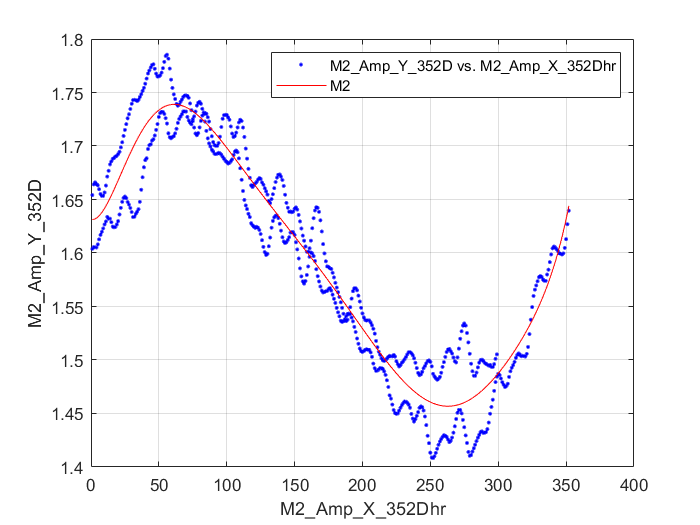

%CREATEFIT(M2_AMP_X_352DHR,M2_AMP_Y_352D)
%  Create a fit.
%
%  Data for 'M2' fit:
%      X Input : M2_Amp_X_352Dhr
%      Y Output: M2_Amp_Y_352D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 21:10:44


%% Fit: 'M2'.
[xData, yData] = prepareCurveData( M2_Amp_X_352Dhr, M2_Amp_Y_352D );

% Set up fittype and options.
ft = fittype( 'poly8' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'M2' );
h = plot( fitresult, xData, yData );
legend( h, 'M2_Amp_Y_352D vs. M2_Amp_X_352Dhr', 'M2', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'M2_Amp_X_352Dhr', 'Interpreter', 'none' );
ylabel( 'M2_Amp_Y_352D', 'Interpreter', 'none' );
grid on

## **2. M2 Phase:** Cubic spline has been used to fit M2_Phase

`           sse: 375.8127`

`       rsquare: 0.8520`

`           dfe: 582.0890`

`    adjrsquare: 0.8348`

`          rmse: 0.8035`

The last column of the `fitresult.coefs `is the values of the regressed data

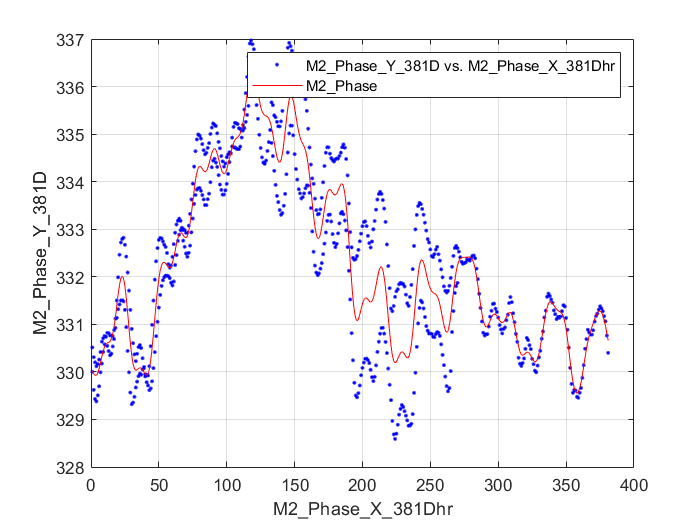

%CREATEFIT(M2_PHASE_X_381DHR,M2_PHASE_Y_381D)
%  Create a fit.
%
%  Data for 'M2_Phase' fit:
%      X Input : M2_Phase_X_381Dhr
%      Y Output: M2_Phase_Y_381D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 24-May-2021 15:51:20


%% Fit: 'M2_Phase'.
[xData, yData] = prepareCurveData( M2_Phase_X_381Dhr, M2_Phase_Y_381D );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.0376481498968531;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'M2_Phase' );
h = plot( fitresult, xData, yData );
legend( h, 'M2_Phase_Y_381D vs. M2_Phase_X_381Dhr', 'M2_Phase', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'M2_Phase_X_381Dhr', 'Interpreter', 'none' );
ylabel( 'M2_Phase_Y_381D', 'Interpreter', 'none' );
grid on

## **3. S2 Amp:** Cubic spline 

`Smoothing spline:`

`       f(x) = piecewise polynomial computed from p`

`Smoothing parameter:`

`       p = 0.0048385678`

`Goodness of fit:`

`  SSE: 0.2328`

`  R-square: 0.9741`

`  Adjusted R-square: 0.9725`

`  RMSE: 0.01951`

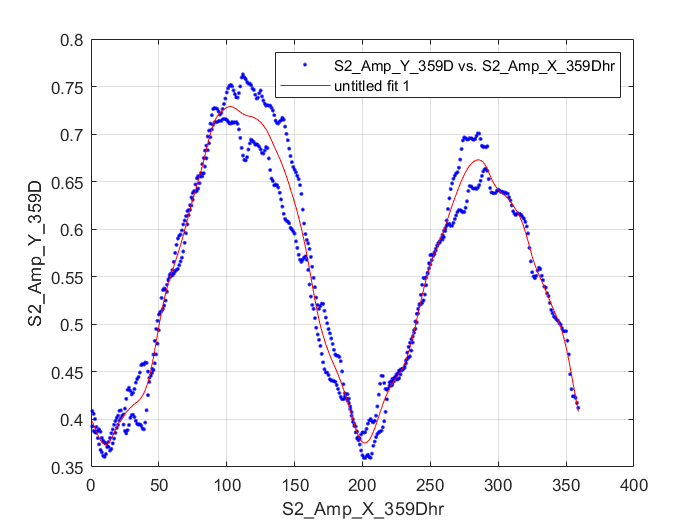

%CREATEFIT(S2_AMP_X_359DHR,S2_AMP_Y_359D)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : S2_Amp_X_359Dhr
%      Y Output: S2_Amp_Y_359D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 18:06:46


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( S2_Amp_X_359Dhr, S2_Amp_Y_359D );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.00483856776923431;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'S2_Amp_Y_359D vs. S2_Amp_X_359Dhr', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'S2_Amp_X_359Dhr', 'Interpreter', 'none' );
ylabel( 'S2_Amp_Y_359D', 'Interpreter', 'none' );
grid on

## **4. S2 Phase:** Cubic spline 

Smoothing spline:

       f(x) = piecewise polynomial computed from p

Smoothing parameter:

       p = 0.090002775

Goodness of fit:

  SSE: 849.2

  R-square: 0.9875

  Adjusted R-square: 0.9856

  RMSE: 1.223


%CREATEFIT(S2_PHASE_X_362DHR,S2_PHASE_Y_362D)
%  Create a fit.
%
%  Data for 'S2_Phase copy 1' fit:
%      X Input : S2_Phase_X_362Dhr
%      Y Output: S2_Phase_Y_362D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 18:21:28


%% Fit: 'S2_Phase copy 1'.
[xData, yData] = prepareCurveData( S2_Phase_X_362Dhr, S2_Phase_Y_362D );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.0900027750358456;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'S2_Phase copy 1' );
h = plot( fitresult, xData, yData );
legend( h, 'S2_Phase_Y_362D vs. S2_Phase_X_362Dhr', 'S2_Phase copy 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'S2_Phase_X_362Dhr', 'Interpreter', 'none' );
ylabel( 'S2_Phase_Y_362D', 'Interpreter', 'none' );
grid on


## **5. N2 Amp:** Sin 7

`General model Sin7:`

`     f(x) =  `

`                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3) + `

`                    a4*sin(b4*x+c4) + a5*sin(b5*x+c5) + a6*sin(b6*x+c6) + `

`                    a7*sin(b7*x+c7)`

`Coefficients (with 95% confidence bounds):`

`       a1 =      0.4634  (-7.895, 8.822)`

`       b1 =    0.007113  (-0.07764, 0.09186)`

`       c1 =      0.1842  (-17.71, 18.07)`

`       a2 =      0.1906  (-7.944, 8.325)`

`       b2 =     0.01475  (-0.1576, 0.1871)`

`       c2 =       1.764  (-32.43, 35.96)`

`       a3 =     0.07021  (-0.191, 0.3314)`

`       b3 =     0.03281  (-0.005014, 0.07063)`

`       c3 =      -1.491  (-8.17, 5.189)`

`       a4 =    0.008354  (-0.03558, 0.05229)`

`       b4 =     0.05351  (-0.002405, 0.1094)`

`       c4 =       0.962  (-10.03, 11.95)`

`       a5 =      0.1371  (-28.15, 28.43)`

`       b5 =      0.2092  (0.1497, 0.2687)`

`       c5 =     -0.6016  (-5.927, 4.723)`

`       a6 =    0.006533  (0.0007179, 0.01235)`

`       b6 =     0.07665  (0.06555, 0.08774)`

`       c6 =       2.208  (-0.2496, 4.665)`

`       a7 =      0.1315  (-28.16, 28.42)`

`       b7 =      0.2097  (0.1476, 0.2719)`

`       c7 =       2.489  (-3.09, 8.067)`

`Goodness of fit:`

`  SSE: 0.1401`

`  R-square: 0.9609`

`  Adjusted R-square: 0.9596`

`  RMSE: 0.01491`

%CREATEFIT(N2_AMP_X_402DHR,N2_AMP_Y_402D)
%  Create a fit.
%
%  Data for 'N2_Amp' fit:
%      X Input : N2_Amp_X_402Dhr
%      Y Output: N2_Amp_Y_402D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 18:36:09


%% Fit: 'N2_Amp'.
[xData, yData] = prepareCurveData( N2_Amp_X_402Dhr, N2_Amp_Y_402D );

% Set up fittype and options.
ft = fittype( 'sin7' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf];
opts.StartPoint = [0.482566307505615 0.00783439564486233 0.0339596352207832 0.215239841351765 0.0156687912897247 1.5705762993709 0.0574876937965551 0.0313375825794493 -1.13124486515073 0.0160882236386007 0.047006373869174 1.91293922520201 0.012042381941991 0.203694286766421 -0.0146890658582894 0.00861948156561161 0.0783439564486233 1.77809578629668 0.0060829851881075 0.219363078056145 1.08053329614172];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'N2_Amp' );
h = plot( fitresult, xData, yData );
legend( h, 'N2_Amp_Y_402D vs. N2_Amp_X_402Dhr', 'N2_Amp', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'N2_Amp_X_402Dhr', 'Interpreter', 'none' );
ylabel( 'N2_Amp_Y_402D', 'Interpreter', 'none' );
grid on


## **6. N2 Phase:** Cubic spline 

`Smoothing spline:`

`       f(x) = piecewise polynomial computed from p`

`Smoothing parameter:`

`       p = 0.24422049`

`Goodness of fit:`

`  SSE: 2513`

`  R-square: 0.9754`

`  Adjusted R-square: 0.9696`

`  RMSE: 2.184`

%CREATEFIT(N2_PHASE_X_418DHR,N2_PHASE_Y_418D)
%  Create a fit.
%
%  Data for 'N2_Phase' fit:
%      X Input : N2_Phase_X_418Dhr
%      Y Output: N2_Phase_Y_418D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 18:53:42

%% Fit: 'N2_Phase'.
[xData, yData] = prepareCurveData( N2_Phase_X_418Dhr, N2_Phase_Y_418D );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.244220491318221;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'N2_Phase' );
h = plot( fitresult, xData, yData );
legend( h, 'N2_Phase_Y_418D vs. N2_Phase_X_418Dhr', 'N2_Phase', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'N2_Phase_X_418Dhr', 'Interpreter', 'none' );
ylabel( 'N2_Phase_Y_418D', 'Interpreter', 'none' );
grid on

## **7. K1_Amp: Polynomial 8 order**

Linear model Poly8:

     f(x) = p1*x^8 + p2*x^7 + p3*x^6 + p4*x^5 + 

                    p5*x^4 + p6*x^3 + p7*x^2 + p8*x + p9

       where x is normalized by mean 165.2 and std 97.31

Coefficients (with 95% confidence bounds):

       p1 =    0.007928  (0.007248, 0.008608)

       p2 =    -0.01413  (-0.01513, -0.01313)

       p3 =    -0.06712  (-0.07113, -0.0631)

       p4 =      0.1052  (0.1004, 0.11)

       p5 =      0.1939  (0.186, 0.2018)

       p6 =     -0.2437  (-0.2504, -0.2369)

       p7 =     -0.1939  (-0.1995, -0.1883)

       p8 =      0.1648  (0.162, 0.1676)

       p9 =      0.2117  (0.2107, 0.2127)

Goodness of fit:

  SSE: 0.02057

  R-square: 0.9796

  Adjusted R-square: 0.9794

  RMSE: 0.005661

%CREATEFIT(K1_AMP_X_361DHR,K1_AMP_Y_361D)
%  Create a fit.
%
%  Data for 'K1 Amp' fit:
%      X Input : K1_Amp_X_361Dhr
%      Y Output: K1_Amp_Y_361D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 19:45:50


%% Fit: 'K1 Amp'.
[xData, yData] = prepareCurveData( K1_Amp_X_361Dhr, K1_Amp_Y_361D );

% Set up fittype and options.
ft = fittype( 'poly8' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'K1 Amp' );
h = plot( fitresult, xData, yData );
legend( h, 'K1_Amp_Y_361D vs. K1_Amp_X_361Dhr', 'K1 Amp', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'K1_Amp_X_361Dhr', 'Interpreter', 'none' );
ylabel( 'K1_Amp_Y_361D', 'Interpreter', 'none' );
grid on

## 8. K1 Phase: Spline This needs manual intervention and data correction.

There are 3 segments of data here: 

#### **Set 1: Day 1 - 118 (Spline equation used)**

#### **Set 2: Day  125 - 151 (Spline equation used)**

#### **Set 3: Day  165 - 364 (Spline equation used)**

## **Manually corrected days: Corrected in excel **

#### **119 120 121 (lower) [ around 0]**

#### **122 123 124 (upper) [ around 350]**

#### **152-157 (lower) [ around 350]**

#### **158-164 (upper) [ around 0]**

`Smoothing spline:`

`       f(x) = piecewise polynomial computed from p`

`Smoothing parameter:`

`       p = 0.98514792`

`Goodness of fit:`

`  SSE: 4.498e+05`

`  R-square: 0.9365`

`  Adjusted R-square: 0.8723`

`  RMSE: 37.31`

%CREATEFIT(K1_PHASE_X_364DHR,K1_PHASE_Y_364D)
%  Create a fit.
%
%  Data for 'K1_Phase' fit:
%      X Input : K1_Phase_X_364Dhr
%      Y Output: K1_Phase_Y_364D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 20:04:20


%% Fit: 'K1_Phase'.
[xData, yData] = prepareCurveData( K1_Phase_X_364Dhr, K1_Phase_Y_364D );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.985147923154858;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'K1_Phase' );
h = plot( fitresult, xData, yData );
legend( h, 'K1_Phase_Y_364D vs. K1_Phase_X_364Dhr', 'K1_Phase', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'K1_Phase_X_364Dhr', 'Interpreter', 'none' );
ylabel( 'K1_Phase_Y_364D', 'Interpreter', 'none' );
grid on

## **9. O1 Amp: Spline**

`Smoothing spline:`

`       f(x) = piecewise polynomial computed from p`

`Smoothing parameter:`

`       p = 0.14120131`

`Goodness of fit:`

`  SSE: 0.01352`

`  R-square: 0.9294`

`  Adjusted R-square: 0.9173`

`  RMSE: 0.004935`



%CREATEFIT(O1_AMP_X_367DHR,O1_AMP_Y_367D)
%  Create a fit.
%
%  Data for 'O1_Amp' fit:
%      X Input : O1_Amp_X_367Dhr
%      Y Output: O1_Amp_Y_367D
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 20:44:39


%% Fit: 'O1_Amp'.
[xData, yData] = prepareCurveData( O1_Amp_X_367Dhr, O1_Amp_Y_367D );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.141201314039198;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'O1_Amp' );
h = plot( fitresult, xData, yData );
legend( h, 'O1_Amp_Y_367D vs. O1_Amp_X_367Dhr', 'O1_Amp', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'O1_Amp_X_367Dhr', 'Interpreter', 'none' );
ylabel( 'O1_Amp_Y_367D', 'Interpreter', 'none' );
grid on

## O1 Phase: Polynomial 8 Robast

`Linear model Poly8:`

`     f(x) = p1*x^8 + p2*x^7 + p3*x^6 + p4*x^5 + `

`                    p5*x^4 + p6*x^3 + p7*x^2 + p8*x + p9`

`       where x is normalized by mean 164.5 and std 96.17`

`Coefficients (with 95% confidence bounds):`

`       p1 =      -1.477  (-2.023, -0.9307)`

`       p2 =    -0.06434  (-0.7863, 0.6576)`

`       p3 =        7.14  (3.888, 10.39)`

`       p4 =       12.34  (8.828, 15.85)`

`       p5 =      -8.756  (-15.14, -2.372)`

`       p6 =      -50.67  (-55.73, -45.62)`

`       p7 =     0.05353  (-4.38, 4.487)`

`       p8 =       41.08  (38.96, 43.2)`

`       p9 =       319.6  (318.8, 320.3)`

`Goodness of fit:`

`  SSE: 1.196e+04`

`  R-square: 0.8723`

`  Adjusted R-square: 0.8708`

`  RMSE: 4.316`

%CREATEFITS(O1_PHASE_X_354DHR,O1_PHASE_Y_354D)
%  Create fits.
%
%  Data for 'O1_Sine' fit:
%      X Input : O1_Phase_X_354Dhr
%      Y Output: O1_Phase_Y_354D
%  Output:
%      fitresult : a cell-array of fit objects representing the fits.
%      gof : structure array with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 25-May-2021 21:03:15

%% Initialization.

% Initialize arrays to store fits and goodness-of-fit.
fitresult = cell( 2, 1 );
gof = struct( 'sse', cell( 2, 1 ), ...
    'rsquare', [], 'dfe', [], 'adjrsquare', [], 'rmse', [] );

%% Fit: 'O1_Spline'.
[xData, yData] = prepareCurveData( O1_Phase_X_354Dhr, O1_Phase_Y_354D );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.0339513163247205;

%% Fit: 'O1_Sine'.
[xData, yData] = prepareCurveData( O1_Phase_X_354Dhr, O1_Phase_Y_354D );

% Set up fittype and options.
ft = fittype( 'poly8' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';

% Fit model to data.
[fitresult{2}, gof(2)] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'O1_Sine' );
h = plot( fitresult{2}, xData, yData );
legend( h, 'O1_Phase_Y_354D vs. O1_Phase_X_354Dhr', 'O1_Sine', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'O1_Phase_X_354Dhr', 'Interpreter', 'none' );
ylabel( 'O1_Phase_Y_354D', 'Interpreter', 'none' );
grid on
